v_on= 10/3.6;
v_off= 25/3.6;
v_gear= 18/3.6;
v= 0;
v_pre= 0;
dt= 0.1;

m=210;
save= [];

for i=1:700
[burn, f_drive]= EngineModel(v_on, v_off, v_gear, v, v_pre);
f_drag= 0.5*0.14*1.15*1.7577*v^2*10;

v_pre= v;
v= v+ (f_drive-f_drag)/m*dt;

save= [save; [burn, f_drive, v*3.6]];
end


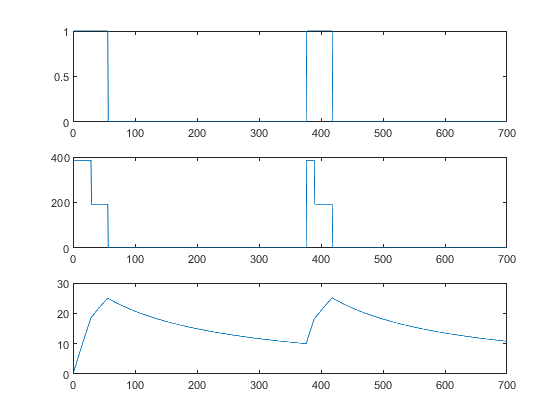

close all;
subplot(3,1,1)
plot(save(:,1))

subplot(3,1,2)
plot(save(:,2))

subplot(3,1,3)
plot(save(:,3))